clc;
clear all;
close all;

run("Q31_Basic.mlx")

sys_dis =
 
   0.1604 z^2 - 0.1958 z + 0.07861
  ----------------------------------
  z^3 - 1.937 z^2 + 1.122 z - 0.1421
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



c =          0    0.1604   -0.1958    0.0786


d =     1.0000   -1.9367    1.1220   -0.1421


sys_cont_close =
 
     7.8 s^3 + 205.7 s^2 + 601.4 s + 1276
  -------------------------------------------
  s^4 + 15.8 s^3 + 212.7 s^2 + 608.4 s + 1276
 
Continuous-time transfer function.


sys_dis_close =
 
  0.1328 z^3 - 0.3505 z^2 + 0.3048 z - 0.08705
  --------------------------------------------
  z^4 - 3.73 z^3 + 5.24 z^2 - 3.288 z + 0.778
 
Sample time: 0.015887 seconds
Discrete-time transfer function.



c1 =          0    0.1328   -0.3505    0.3048   -0.0871


d1 =     1.0000   -3.7296    5.2395   -3.2878    0.7780


## generate data

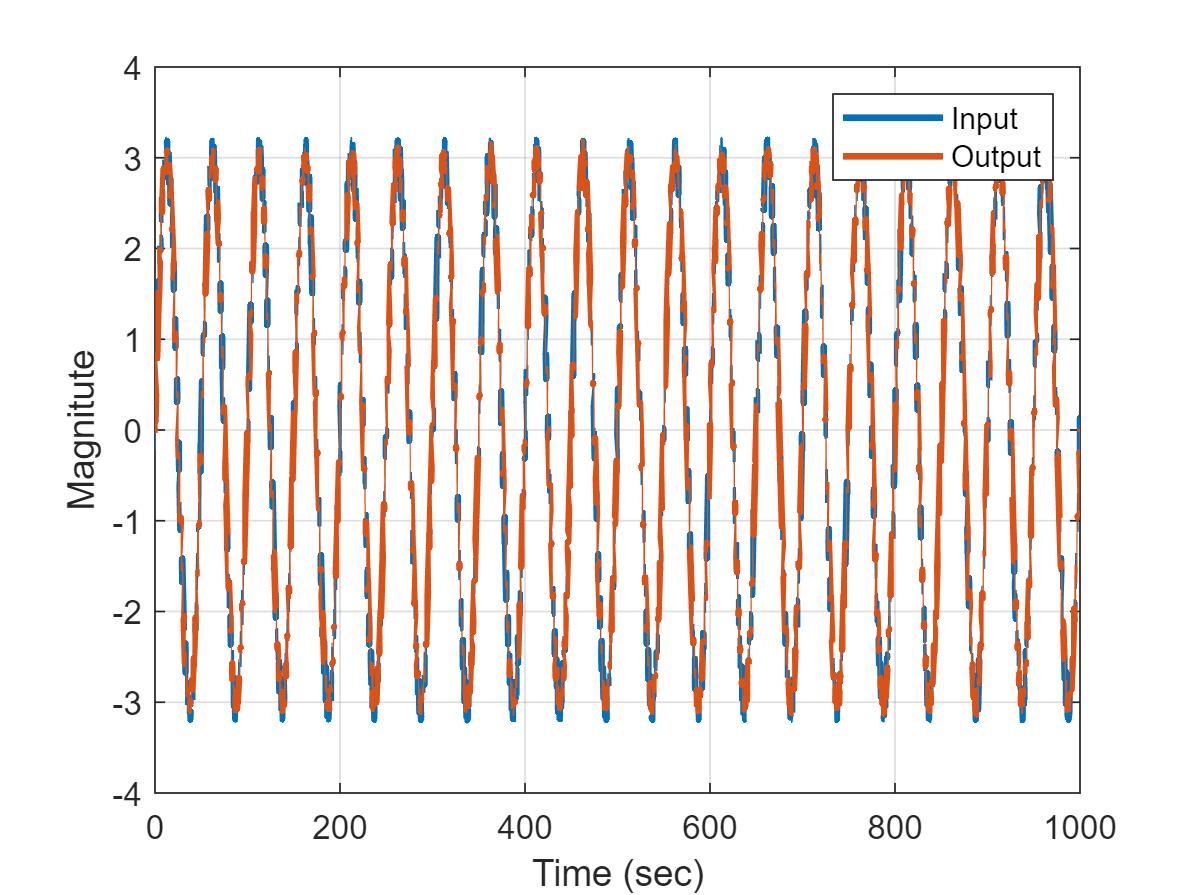

tfinal=1000;
t = 0:T_s_close:tfinal;
u = 3*gensig('sine' , tfinal/20 , tfinal ,T_s_close);
Noise=(-0.2+(0.2+0.2)*rand(numel(t),1));
u=u+Noise;
y = lsim(sys_dis_close ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitute') ;
grid on
legend('Input','Output') ;

kalman Filter

N = numel(y) ;
%--------------------------%
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

%--------------------------%
Nv=Parameters_in_num+Parameters_in_den;
theta(:,1:Nv) = zeros(Nv , Nv) ;
P=[Nv,Nv];
P= 1e16*eye(Nv); 
phi=[Nv,N];
phi(1:Nv,1:N) = zeros(Nv , N) ;

Landa=1;
Sigma_e=(-0.1+(0.1+0.1)*rand(Nv,1));

for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]']';
    K = P*phi(:,i)*(Landa+phi(:,i)'*P*phi(:,i))^(-1);
    P =P-(K*phi(:,i)'*P/Landa)*(Landa + phi(:,i)'*P*phi(:,i))^(-1) ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1))+Sigma_e.^2; 
    Sigma_e=-0.05+(0.05+0.05)*rand(Nv,1);
end

Bode

ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s_close)

ident_dis =
 
   0.1223 z^3 + 0.02657 z^2 - 0.01611 z - 0.05414
  -------------------------------------------------
  z^4 - 0.8442 z^3 - 0.2554 z^2 - 0.2093 z + 0.4186
 
Sample time: 0.015887 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
      7.872 s^3 + 375.5 s^2 + 1.657e05 s + 2.928e06
  ------------------------------------------------------
  s^4 + 54.81 s^3 + 2.108e04 s^2 + 3.065e05 s + 4.084e06
 
Continuous-time transfer function.



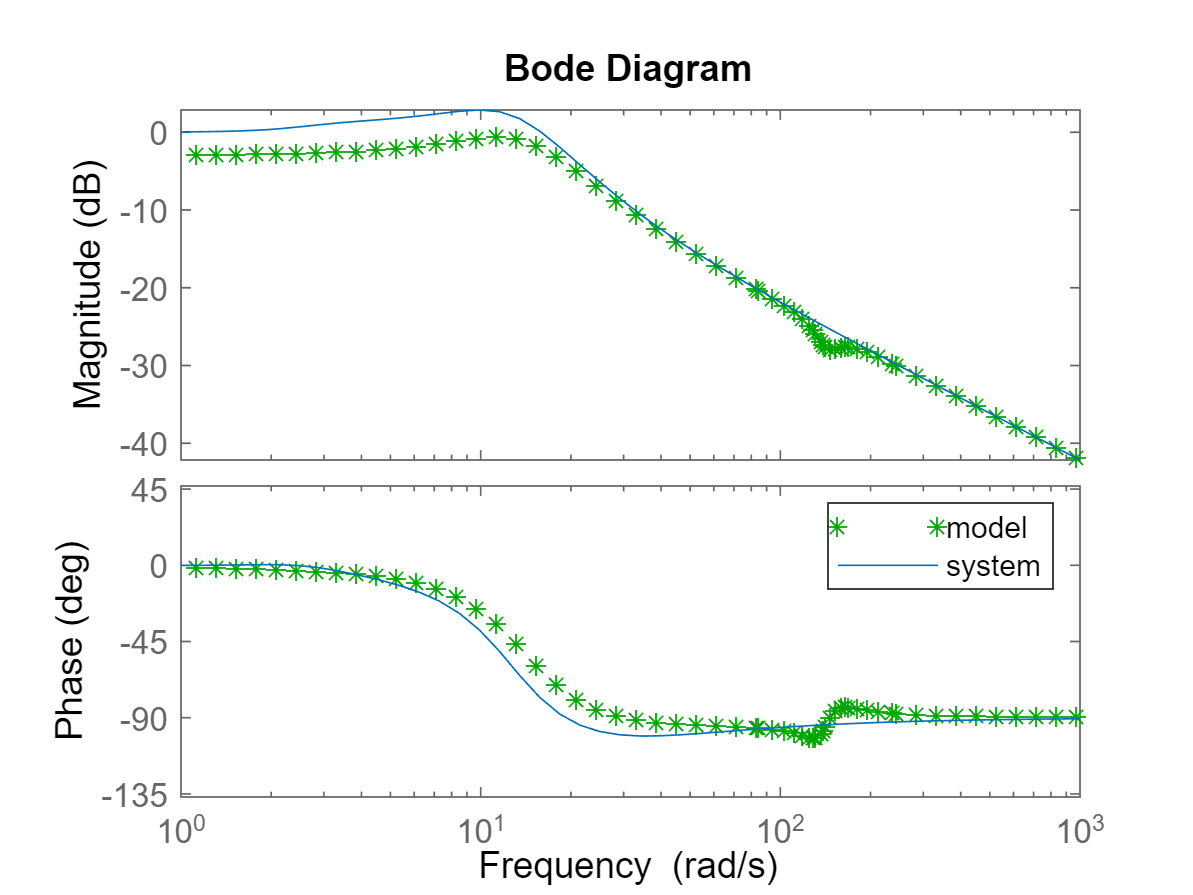

bode(ident_analog ,'g*',sys_cont_close )
legend('model ','system')

KF Convergence

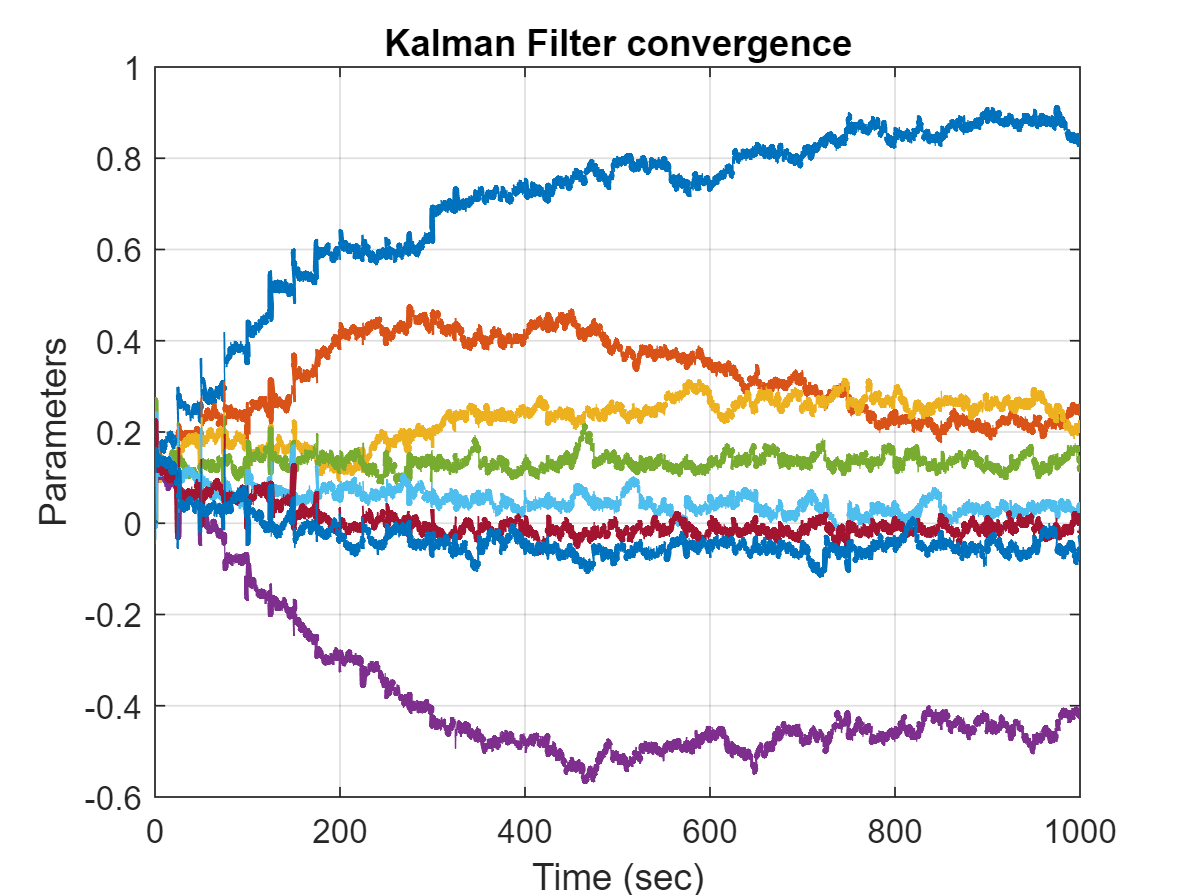

plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('Kalman Filter convergence') ;
grid on